# Programmatically Number Pages

These examples show how to number pages of a report programmatically with both the DOM and Report APIs. This workflow applies only to Word and PDF output.

## Simple Page Numbers Using the DOM API

In this example, each page contains a footer with the page number in Arabic numerals. Here is the first page:

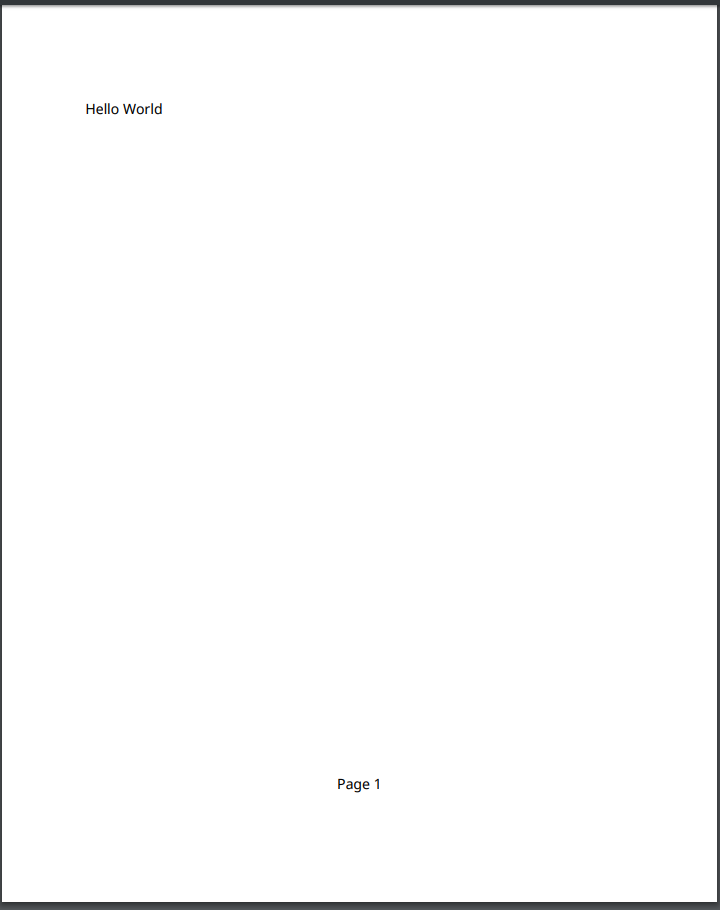

Import the DOM package so that you do not have to use long, fully qualified class names.

import mlreportgen.dom.*;

Create and open a PDF document. To create a Word document, change the output type from `"pdf"` to `"docx"`.

d = Document("pageNumberExample","pdf");
open(d);

Create a PDF footer and add it to the current page layout. Set the type of the footer to `"default"` so that it appears on all pages of the document. If the document is a Word document, create a `DOCXPageFooter` instead of a `PDFPageFooter`.

footer = PDFPageFooter("default");
d.CurrentPageLayout.PageFooters = footer;

Define a `Paragraph` object containing the text appearing before the page number. Format the paragraph so that it is centered horizontally on the page.

pagePara = Paragraph("Page");
pagePara.WhiteSpace = "preserve";
pagePara.HAlign = "center";

Create a DOM `Page` object that is a placeholder for a page number. This placeholder will be replaced by the current page number when the PDF document is written, or when the Word document is opened in Word. This `Page` object can be added directly to a footer or header, but this example includes some extra text and formatting with the page number.

pageNum = Page();

Append the page number to the paragraph and add the paragraph to the footer.

append(pagePara,pageNum);
append(footer,pagePara);

Demonstrate the page numbering by adding paragraphs and page breaks to the document to create several pages.

page1Para = Paragraph("Hello World");
append(d,page1Para);

append(d, PageBreak());
page2Para = Paragraph("Another page");
append(d,page2Para);

append(d, PageBreak());
page3Para = Paragraph("Another page");
append(d,page3Para);

Close and view the document.

close(d);
rptview(d);

## Customized Page Numbers Using the DOM API

This example demonstrates different ways that you can customize page numbering in a document. A DOM `PageNumber` object sets the page numbering to begin at 4 and the number format to uppercase Roman numerals. A different setting in the page header object causes only even pages to have a header. Here are the tops of each page in the document:

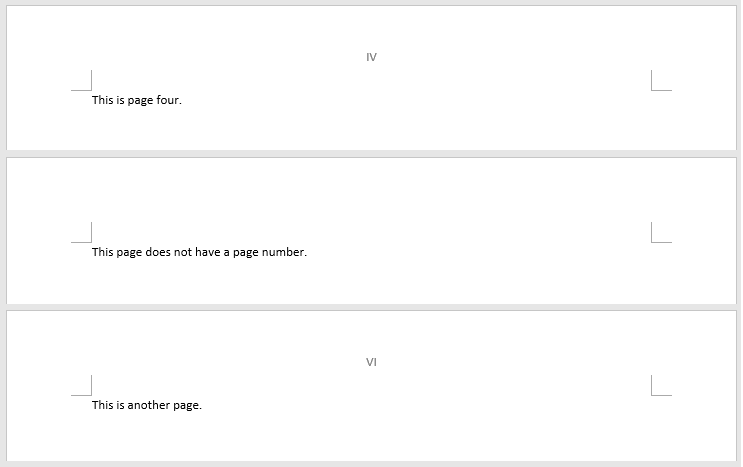

Import the DOM package so that you do not have to use long, fully-qualified class names.

import mlreportgen.dom.*;

Create and open a Word document. To create a PDF document, change the output type from `docx` to `pdf`.

d = Document("customPageNumberExample","docx");
open(d);

Create a `PageNumber` object to specify that the page numbers start at 4 and use uppercase Roman numerals. Add the object to the current page layout of the document.

romanPageNumber = PageNumber(4,"I");

layout = d.CurrentPageLayout;
layout.Style = [layout.Style {romanPageNumber}];

Create a header and add it to the current page layout. Set the type of the header to `even` so that it is included only on even pages of the document. If the document is a PDF document, create a `PDFPageHeader` instead of a `DOCXPageHeader`.

evenPageHeader = DOCXPageHeader("even");
layout.PageHeaders = evenPageHeader;

Create a paragraph containing a page number placeholder. Set the paragraph's `HAlign` property so that the page number is centered in the header. Add the paragraph to the header.

headerPara = Paragraph();
headerPara.HAlign = "center";
append(headerPara,Page());

append(evenPageHeader,headerPara);

Demonstrate the page numbering by adding paragraphs and page breaks to the document to create several pages.

page4Para = Paragraph("This is page four.");
append(d,page4Para);

append(d, PageBreak());
page5Para = Paragraph("This page does not have a page number.");
append(d,page5Para);

append(d, PageBreak());
page6Para = Paragraph("This is another page.");
append(d,page6Para);

Close and view the document.

close(d);
rptview(d);

## Page Numbers Using the Report API

Page numbers are automatically included in reports made with the Report API. You can set the starting number and number format for the entire report or for individual chapters. In this example, the default number format for the report is Arabic numerals, but the last chapter overrides this setting to use uppercase alphabetic characters. The table of contents demonstrates the page numbering setup:

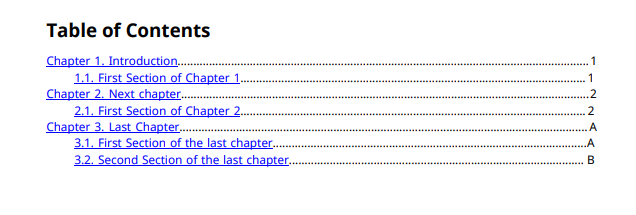

Import the Report and DOM packages so that you do not have to use long, fully-qualified class names.

import mlreportgen.report.*
import mlreportgen.dom.*

Create a PDF report. To create a Word report, change the output type from `pdf` to `docx`. You can set the first page number and number format for the entire report by modifying the `PageNumberFormat` and `FirstPageNumber` properties of the report object's `Layout` property, as shown in the commented lines of code. Because the default page numbering is Arabic numerals beginning with 1, you do not have to set the properties for this example.

rpt = Report("newReport", "pdf"); 
% rpt.Layout.PageNumberFormat = "n";
% rpt.Layout.FirstPageNumber = 1;

Create a title page and table of contents. Add them to the report. The title page has no page number. The table of contents is numbered by default with lowercase Roman numerals beginning with `i`. To change the table of contents numbering, use the `Layout` property of the object as shown in the commented code for the `Report` object.

tp = TitlePage();
tp.Title = "New Report"; 
tp.Author = "MathWorks"; 
add(rpt,tp);

toc = TableOfContents();

add(rpt, toc);

Create two chapters using the default page number and format of the report. Add them to the report.

ch = Chapter("Introduction");
sec = Section("First Section of Chapter 1");
add(sec, "This is the first section of chapter 1.");
add(ch,sec);
add(rpt,ch); 

ch = Chapter("Next chapter"); 
sec = Section("First Section of Chapter 2"); 
add(sec,"This is the first section of chapter 2.");
add(ch,sec);
add(rpt,ch)

Create a final chapter for the report. Set the starting page number back to 1 and the number format to uppercase alphabetic characters. 

ch = Chapter("Last Chapter");
ch.Layout.FirstPageNumber = 1;
ch.Layout.PageNumberFormat = "A";

Create two sections separated by a page break and add them to the report to demonstrate the page numbering of the final chapter.

sec = Section("First Section of the last chapter"); 
add(sec,"This is the first section of the last chapter.");
add(ch,sec);

add(ch, PageBreak());

sec = Section("Second Section of the last chapter"); 
add(sec,"This is the second section of the last chapter.");
add(ch,sec);

add(rpt, ch);

Close and view the report.

close(rpt);
rptview(rpt);

*Copyright 2018 The MathWorks, Inc.*